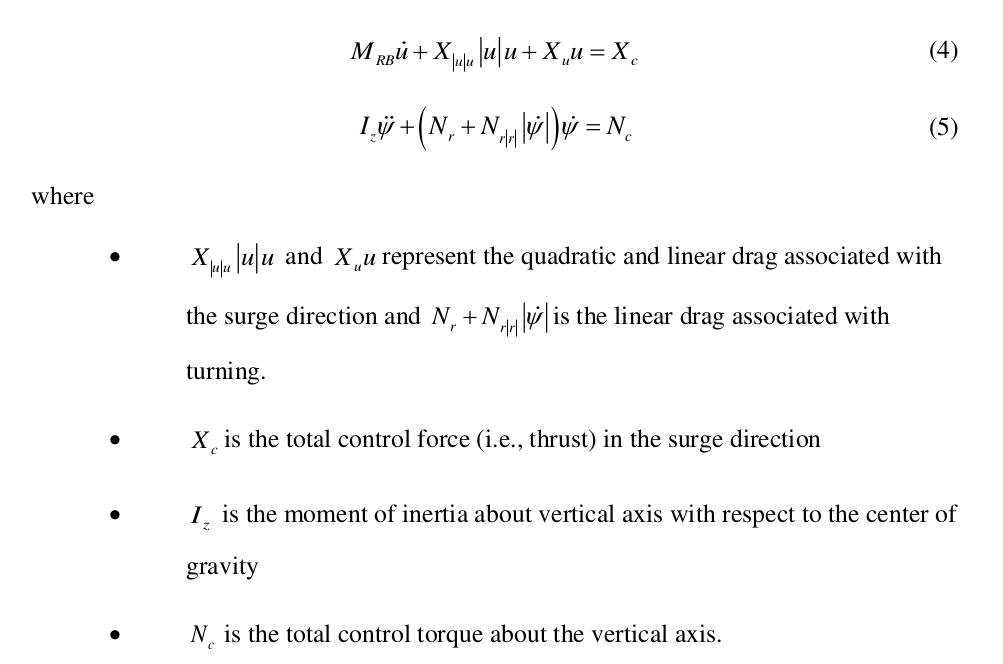

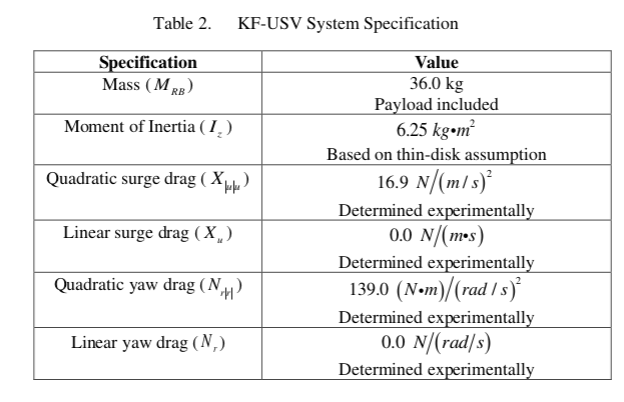

function dxdt = usv_pd(t, x, pd)
    if nargin < 3
        P = 1000;
        D = 0;
    else
        P = pd(1);
        D = pd(2);
    end
    Iz = 6.25;
    Nrr = 139;
    Nr = 0;
    yg = 1;
    y = x(1);
    dy = x(2);
    Nc = (yg - y)*P - dy*D;
    dxdt(1,1) = dy;
    dxdt(2,1) = 1/Iz*( -1*(Nr + Nrr*abs(dy))*dy + Nc);
end



dxdt = usv_pd(0, [0 0])

dxdt =      0
   160


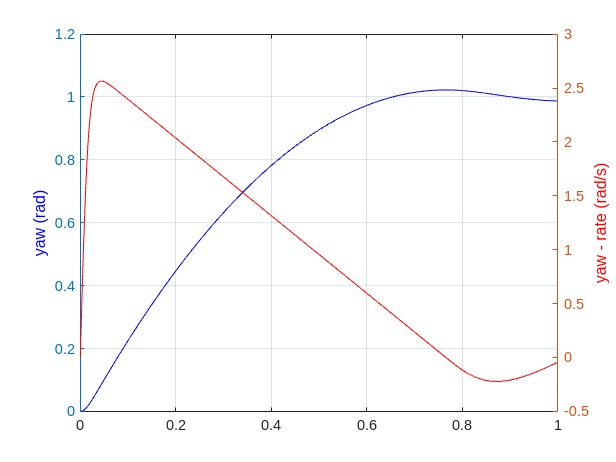

[tt, xx] = ode45(@usv_pd, [0 1], [0; 0]);
figure;
clf;
yyaxis left
plot(tt,xx(:,1), 'b')
ylabel('yaw (rad)', 'Color', 'b')
grid('on')
yyaxis right
plot(tt,xx(:,2), 'r')
ylabel('yaw - rate (rad/s)', 'Color','r')


si = stepinfo(xx(:,1),tt)

si = struct with fields:
         RiseTime: 0.4437
    TransientTime: 0.8725
     SettlingTime: 0.8725
      SettlingMin: 0.8953
      SettlingMax: 1.0225
        Overshoot: 3.5875
       Undershoot: 0
             Peak: 1.0225
         PeakTime: 0.7663


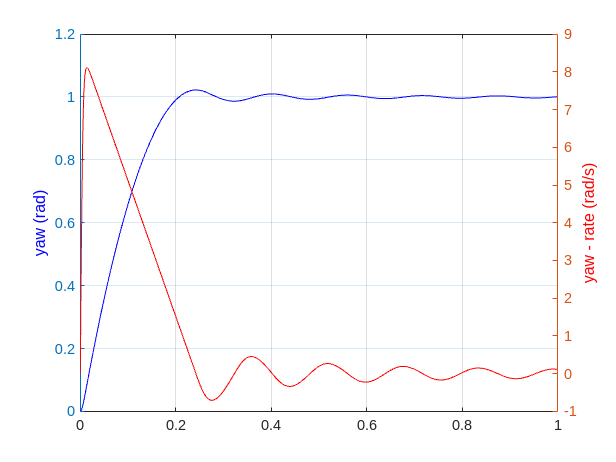


pd = [10000 0];
odefun = @(t,y) usv_pd(t, y, pd);
[tt, xx] = ode45(odefun, [0 1], [0; 0]);
figure;
clf;
yyaxis left
plot(tt,xx(:,1), 'b')
ylabel('yaw (rad)', 'Color', 'b')
grid('on')
yyaxis right
plot(tt,xx(:,2), 'r')
ylabel('yaw - rate (rad/s)', 'Color','r')




function cost = pd_performance(pd)
    odefun = @(t,y) usv_pd(t, y, pd);
    [tt, xx] = ode45(odefun, [0 1], [0; 0]);
    si = stepinfo(xx(:,1),tt);
    cost = si.RiseTime + si.Overshoot;
end

pd0 = [1000; 0];
c = pd_performance(pd0)

c = 4.0313


[pd_opt, cost_opt] = fminsearch(@pd_performance, pd0)

pd_opt =   592.4765
    0.0011


cost_opt = 0.6197